addpath("helpers")
clear cube
data_src = "C:\Users\kpiec\OneDrive - Politechnika Łódzka\Studia\2Sem3\magisterka\pomiary\IWR1843BOOST\hall-along_side_run_0\measurement_001";

dr = dca1000FileReader("RecordLocation",data_src);
iwr = IWR1843(data_src);
srcParts = split(data_src,"\");
dataName = join(srcParts(end-1:end),"-");
clear srcParts

dRes=iwr.config.RangeResolution;

guardCells =      3     2


trainCells =      4     2


numFrames = 702

% [rangeCellsNum angleCellsNum]
guardCells = [round(.2/dRes) 2]
trainCells = [round(.3/dRes) 2]
falseAlarmProbability = 3e-4;
detector = phased.CFARDetector2D("Method","GOCA","ProbabilityFalseAlarm",falseAlarmProbability,"GuardBandSize",guardCells, ...
    "TrainingBandSize",trainCells);

rangeLimits=[0.5 4]; % m
angFftLength=32;

numFrames=min([dr.NumDataCubes 900])
angLimits=iwr.scanAnglesRange;

cube=dr.read(1,1);
cube = iwr.arrangeVirtualDataAngleULA(cube);
mcrDopSize=flip(size(cube)); % dop,rx,range
mcrDopSize(3)=numFrames; % dop,rx,frame
mcrDop=zeros(mcrDopSize);
mcrDopTime=(1:numFrames)*iwr.config.FramePeriodicity*1e-3;
clear mcrDopSize

angGrid=iwr.mvdrEstimator.ScanAngles;

rngWin=hamming(iwr.config.SamplesPerChirp);
dopWin=hamming(iwr.config.NumChirps/sum(iwr.config.ActiveTransmitters))';
bg = zeros(size(cube));

for i=1:numFrames
% for i=82:90
    srcCube = dr.read(1,i);
    srcCube = iwr.arrangeVirtualDataAngleULA(srcCube);
    cube = fft(srcCube.*rngWin,[],1); % fast time FFT

    cube = cube(rngIdxs,[1:4 9:12],:); % cut cube to rangeLimits and skip middle TX
    cube = fftshift(fft(cube.*reshape(rngWin, 1, 1, []),[],2),2); % angle FFT
    cube = fftshift(fft(cube.*reshape(dopWin, 1, 1, []),[],3),3); % slow time (Doppler) FFT
    
    [resp,rngGrid,dopGrid] = iwr.rdResponse(srcCube);
    [rngIdxs, rngGrid]= getLimitedIndexRangesFromDataRanges(rngGrid, rangeLimits);
    resp = resp(rngIdxs,:,:);
    mcrDop(:,:,i)=squeeze(sum(resp,1))';
    % plot mean from each rx
    % figure(1);
    % hold on;
    % imagesc(dopGrid,rngGrid,squeeze(abs(resp)));
    % colormap('gray');
    % hold off;
    % set(gca, 'YDir','normal');
    % xlabel('Prędkość (m/s)');
    % ylabel('Odległość (m)');
    % title('Wykres Range-Doppler');
    % ylim(rangeLimits);
    % saveToGif(data_src,"RD");
    continue
     
    
    angfft=zeros(size(angdata,1),numel(iwr.mvdrEstimator.ScanAngles));
    for i=1:size(angdata,1)
        for j=1:2:size(angdata,3)
            if sum(abs())
                angfft(i,:,j)=iwr.mvdrEstimator(angdata(i,:,j));
            end
        end
    end
    angfft = sum(angfft,3);

    figure(2);
    hold on;
    imagesc(angGrid,rngGrid,angfft);
    colormap('gray');
    set(gca, 'YDir','normal');
    xlabel('Kąt (°)');
    ylabel('Odległość (m)');
    title('Wykres Angle-Range');
    ylim(rangeLimits);
    xlim([-90,90]);
    dets = runCFAR2D(detector,angfft);
    targets=[angGrid(dets(2,:)); rngGrid(dets(1,:))'];
    if numel(targets)>0
        plot(targets(1,:),targets(2,:),'o','MarkerFaceColor','red','MarkerEdgeColor','red');
    end
    hold off;
    saveToGif(data_src,"RA");
    continue

    
    
    

    % figure(4);
    % % MVDR
    
    % hold on;
    % imagesc(angGrid,rngGrid,angfft);
    % colormap('gray');
    % set(gca, 'YDir','normal');
    % xlabel('Kąt (°)');
    % ylabel('Odległość (m)');
    % title('Wykres Angle-Range');
    % ylim(rangeLimits);
    % dets = runCFAR2D(detector,angfft);
    % targets=[angGrid(dets(2,:)); rngGrid(dets(1,:))'];
    % plot(targets,'o','MarkerFaceColor','red','MarkerEdgeColor','red');
    % hold off;
    % saveToGif(data_src,"RA-MVDR");

    figure(3);
    [X,Y]=pol2cart(deg2rad(targets(1,:)),targets(2,:));
    plot(Y,X,'o');
    ylim(rangeLimits);
    xlim([-2 2]);
    saveToGif(data_src,"DET");
    drawnow;
end

figure;
avg=10; % frames
bgSpeedLimit=0.1; % m/s
winLen=25; % frames

maxFr=numFrames-winLen;
out = abs(squeeze(mcrDop(:,4,:)));

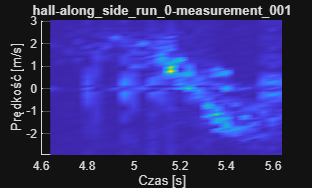

fr = 80;

% showMicroDoppler(mcrDopTime(fr:fr+winLen),dopGrid,out(:,fr:fr+winLen),dataName);
showMicroDoppler(mcrDopTime(fr:fr+winLen),dopGrid,removeMicroDopplerBg(out(:,fr:fr+winLen),bgSpeedLimit,dopGrid,avg),dataName);

function data=removeMicroDopplerBg(mcrDop,bgLimit, dopGrid, movMeanLen)
    data = mcrDop; %dop,frames
    [idxs,~]=getLimitedIndexRangesFromDataRanges(dopGrid,[-bgLimit bgLimit]);
    data(idxs,:) = abs(data(idxs,:) - movmean(data(idxs,:),movMeanLen,2));
end

function showMicroDoppler(mcrDopGrid,dopGrid,data,plotTitle)
    surf(mcrDopGrid,dopGrid,data);
    shading interp;
    title(plotTitle, 'Interpreter', 'none')
    xlabel("Czas [s]")
    ylabel("Prędkość [m/s]")
    ylim(sort(dopGrid([1 end])))
    % view([0 4])
    view([0 90])
end
function [indexArr,croppedRange]=getLimitedIndexRangesFromDataRanges(srcRange,limits)
    if iscolumn(limits)
        limits = limits';
    end
    if xor(isrow(srcRange),isrow(limits))
        [~,startStop] = min(abs(srcRange-limits));
    else
        [~,startStop] = min(abs(srcRange'-limits));
    end
    startStop=sort(startStop);
    indexArr=startStop(1):startStop(2);
    croppedRange = srcRange(indexArr);
end

function detections=runCFAR2D(detector, data)
    % get indexes of limits
    [xMax,yMax] = size(data);
    offset = detector.TrainingBandSize+detector.GuardBandSize+1;
    % create a map of cells to test
    [rowInds,columnInds] = meshgrid(offset(1):(xMax-offset(1)),offset(2):(yMax-offset(2)));
    CUTIdx = [ rowInds(:) columnInds(:)]';
    detections = CUTIdx(:,detector(data,CUTIdx));
end

function saveToGif(data_src,name)
    exportgraphics(gcf,data_src+'\'+name+'.gif','Append',true);
end
function ret=removeMean(data,ax)
    ret = data - mean(data,ax);
end
